# Equation fitting for data obtained from ImageJ particle tracking and @msdanalyzer diffusion analysis

Prior to running this code, you need to download and install @msdanalyser from here: [https://tinevez.github.io/msdanalyzer/](https://tinevez.github.io/msdanalyzer/) @msdanalyzer imposes that the tracks you give to it are formatted in the following way: [ Ti Xi Yi ...]. So if we generate a track with 50 measurements in a 2D diffusion problem, we must generate a 50 x 3 double array per particle. The input file for this code should be a cell, where each array is the [ Ti Xi Yi ] matrix for each particle trajectory. Use the code "tracks_from_ImageJ_data" to convert ImageJ data to tracks cell needed as input here. Import track data in the cell format required for analysis with @msdanalyzer.

Soli Deo Gloria

## Compute some constants needed later

%%%%%%%%%%% Must run this

N_TIME_STEPS = 1428; % This will be needed for plotting the histogram of velocities
SPACE_UNITS = 'um'; % The units are needed to initiate the @msdanalyzer
TIME_UNITS = 's';


% Compute some parameters we will need for fitting the velocity histograms
kB = 1.38064852*(10^(-23)); % Boltzmann constant in units of [(m^2)*kg*(s^-2)*(K^-1)]
t_d = 0.03; % Dust temperature in units of [eV] (assumed equal to room temperature)
T_d = t_d*(1.602176634*10^(-19)); %dust temperature in units of [J]
K_d = T_d/kB; %dust temp in units of Kelvin
r_d = 4.6*(10^(-6)); %radius of spherical dust particles in units of [m]
V_d = (4/3)*pi*(r_d)^3; %volume of a single dust particle in units of [m^3]
rho_d = 1500; %density of dust particle material in units of [kg*(m^-3)]
%(here melamine-formaldehyde)
m_d = V_d*rho_d; %mass of a single dust particle
v_d = sqrt(T_d/m_d)*10^(6); %dust thermal speed in units of [um/s]

## Creating MSD and Essential MA object 

ma = msdanalyzer(2, SPACE_UNITS, TIME_UNITS); %dimensionality and Specify units for the msdanalyzer
ma = ma.addAll(NoDriftTracks); % Add the sample tracks 
ma = ma.computeDrift('velocity');
ma = ma.computeVCorr;

Computing velocity autocorrelation of 8158 tracks... Done.


ma = ma.computeMSD;% Compute MSD for each particle.

Computing MSD of 8158 tracks...  8Done.


ma.msd

ans = 8158×1 cell array
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}


save(['46Pa_07mA_msd_data_Cam1_nhds'],'ma') % Save msd for specific case 

## Separate MSD for X and Y

%%Computing MSD for x component seperately 
%%seperately and then the workspace must be cleared to do 
%%the next msd calculation and graph fitting
%%first load the msd data ma object 
%%example: Total70Pa_0_35mA_msd_data.mat

tracks=ma.tracks;
ma=ma.computeDrift('velocity');

xtracks = [];
for i=1:numel(tracks);
    particle = tracks{i,1}; %this pulls the i'th particle out of the cell tracks
    xtracks{i,1} = particle(:,[1,2]); %this puts the time and position columns into a new cell
end 

%create separate ma object called xma 
xma = msdanalyzer(1, SPACE_UNITS, TIME_UNITS);
xma = xma.addAll(xtracks); % Add the sample tracks for x 
xma = xma.computeDrift('velocity');
%xma = xma.computeVCorr;
xma = xma.computeMSD; % Compute MSD for each particle.

Computing MSD of 100 tracks...   Done.


xma.msd

ans = 100×1 cell array
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}


save(['MDPX_B2_02_rf1_06_P10_3Pa_xMSD'],'xma') % Save x msd for specific case 

%%Computing MSD for y component seperately 
%%example: Total70Pa_0_35mA_msd_data.mat
 
ma=ma.computeDrift('velocity');
tracks=ma.tracks;

ytracks = [];
for i=1:numel(tracks);
    particle = tracks{i,1}; %this pulls the i'th particle out of the cell tracks
    ytracks{i,1} = particle(:,[1,3]);
end 

yma = msdanalyzer(1, SPACE_UNITS, TIME_UNITS);
yma = yma.addAll(ytracks); % Add the sample tracks for y 
yma = yma.computeDrift('velocity');
%yma = yma.computeVCorr;
yma = yma.computeMSD; % Compute MSD for each particle.

Computing MSD of 100 tracks...   Done.


yma.msd

ans = 100×1 cell array
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}
    {800×4 double}


save(['MDPX_B2_02_rf1_06_P10_3Pa_yMSD'],'yma') % Save y msd for specific case into current path

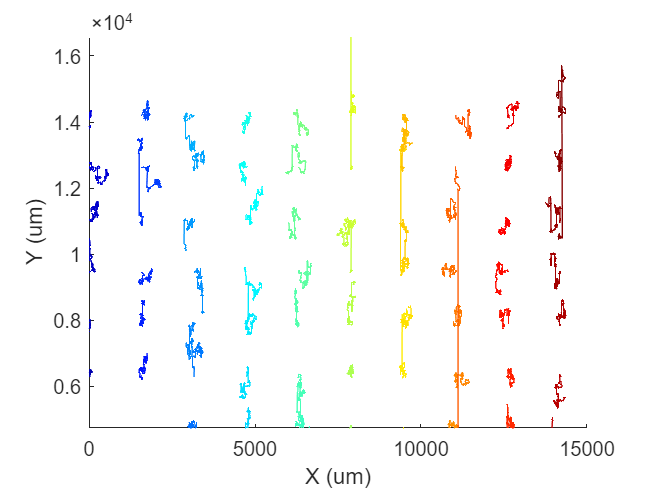

%%Double check all tracks and look at drift for conceptual understanding 
%%and experimental verification
ma = ma.computeDrift('velocity');% Drift is added to the object ma and will be used in further analysis
figure
axis([0 15000 -5000 6000])
ma.plotTracks
ma.labelPlotTracks


% %these are optional
% ma = ma.computeVCorr;
% figure
% ma.plotMeanVCorr
% figure
% ma.plotDrift

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%create drift over time plot%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dtimex=ma.drift(:,1);
dposx=ma.drift(:,2);
xdrift = (dposx(end)-dposx(1))./(dtimex(end)-dtimex(1));

dtimey=ma.drift(:,1);
dposy=ma.drift(:,3);
ydrift = (dposy(end)-dposy(1))./(dtimey(end)-dtimey(1));

figure;
hold on
xlabel('Time (seconds)')
ylabel('Position (um)')
plot(dtimex,dposx);
plot(dtimey,dposy);
title('Drift over Time MDPX B2.02 rf1.06 P10.3Pa');
legend(['x-velocity drift=' num2str(xdrift)],['y-velocity drift=' num2str(ydrift)]);

## Creating Tracks without Drift

%%run the above code first to observe amount of drift

tracks = ma.tracks;
Total_drift = ma.drift;
roundedTotal_drift=round(Total_drift(:,1),4);
number_particles=numel(tracks);

track_nodrift=[];

for i=1:number_particles;
    particle=tracks{i,1};
    time = particle(:,1);
    framecount = numel(particle)/3; %not an actuall timejust a counter for each particle. 
    % It is divided by 3 because numel(particle) counts amount of time
    % data, x data, and y data, thus divide by 3 since the length of all of
    % these is the same
    % Extract data from Total_drift array based on matching values in ith particle time array
    roundedtime = round(time,4);
    matchingRows = ismember(roundedTotal_drift(:, 1), roundedtime);
    drift = Total_drift(matchingRows, 2:3);
    
    particle_nodrift=zeros(framecount,1);
    for j=1:framecount;
        particle_nodrift(j,1:2) = particle(j,2:3)-drift(j,1:2);
    end

    track_nodrift{i,1}=particle_nodrift;

end

%%%PLot N tracks with no drift%%%
figure
axis([0 15000 -1000 4000])
hold on

N = 1000; % Set the desired number of tracks to see. for all set N=numel(track_nodrift)
M = numel(track_nodrift);

for i = 1:min(N, numel(track_nodrift))
    plot(track_nodrift{i}(:, 1), track_nodrift{i}(:, 2));
end
title(['C1 Tracks with drift subtraction 30Pa 07mA ' num2str(N) 'above10frs']);

%%%Plot N tracks with drift%%%
figure
axis([0 15000 -1000 4000])
hold on

N = 1000; % Set the desired number of tracks to see. for all set N=numel(track_nodrift)
M = numel(tracks);

for i = 1:min(N, numel(tracks))
    plot(tracks{i}(:, 2), tracks{i}(:, 3));
end
title(['C1 Tracks with drift 30Pa 07mA ' num2str(N) 'above10frs']);


## Breaking into Subsections

tracks = ma.tracks;
xdomain=0:3750:15000;
ydomain=0:700:2100;
dom11tracks=[];
dom12tracks=[];
dom13tracks=[];
dom14tracks=[];

dom21tracks=[];
dom22tracks=[];
dom23tracks=[];
dom24tracks=[];

dom31tracks=[];
dom32tracks=[];
dom33tracks=[];
dom34tracks=[];


for i=1:numel(tracks)
    if xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom11tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom12tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom13tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom14tracks{i}=tracks{i};

    elseif xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom21tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom22tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom23tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom24tracks{i}=tracks{i};
    
    elseif xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom31tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom32tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom33tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom34tracks{i}=tracks{i};
    end
end


% Remove empty cells from the horizontal cell array and  Convert to a vertical cell array
alldomtracks = {dom11tracks,dom12tracks,dom13tracks,dom14tracks,dom21tracks,dom22tracks,dom23tracks,dom24tracks,dom31tracks,dom32tracks,dom33tracks,dom34tracks};

AllDomTracks=[]; %remove empty doubles from each cell and make vertical

for i=1:numel(alldomtracks);
    currentTracks = alldomtracks{i};
    currentTracks = currentTracks(~cellfun('isempty', currentTracks));
    currentTracks = reshape(currentTracks, [], 1);
    AllDomTracks{i}=currentTracks;
end



%Plot a certain amount of tracks of whatever subsection for viewing
%purposes
hold on
figure
axis([0 15000 -1000 4000])

for i=1:12
    currentdomtracks=AllDomTracks{i};
    for j = 1:min(200,numel(currentdomtracks))
        hold on
        plot(currentdomtracks{j}(:, 2), currentdomtracks{j}(:, 3));
    end
   
end


tracksize=0;
for i=1:numel(AllDomTracks)
    current=AllDomTracks{i};
    n=numel(current);
    tracksize=tracksize+n;
end
traksize

SPACE_UNITS = 'um'; 
TIME_UNITS = 's';
%%Find each ma object info for each domain%%
Allma=[];

for i=1:numel(AllDomTracks);
    ctracks=AllDomTracks{:,i};
    currentma = msdanalyzer(2, SPACE_UNITS, TIME_UNITS); %dimensionality and Specify units for the msdanalyzer
    currentma = currentma.addAll(ctracks); % Add the sample tracks 
    currentma = currentma.computeDrift('velocity');
    currentma = currentma.computeVCorr;
    currentma = currentma.computeMSD;% Compute MSD for each particle.
    Allma{i}=currentma;
end

save(['30Pa_0.7mA_domain_split_ma_Cam1_'],'Allma') % Save msd for specific case into current path

figure
title('Combined Drift over all 12 Domains 70Pa 0.35mA');
ma.plotDrift

AllDomDrift=[];

for domain=1:numel(Allma);
    tma=Allma{domain};
    currentdrift=tma.drift;
    AllDomDrift{domain}=currentdrift(:,2:3);
end


figure
title('Separate Drift of All 12 Domains in 30Pa 0.7mA');

blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9; 0 0.65 0.98];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7; 1 0.2 0.6];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7; 0.6 0.95 0.6]; % Shades of green

for domain=1:12

    if domain <= 4
        colorSet = blueShades(domain,:);
    elseif domain <= 8
        colorSet = redShades(domain-4,:);
    else
        colorSet = greenShades(domain-8,:);
    end
    
   lineColor = colorSet(rem(domain, size(colorSet, 1))+1, :);

    hold on
    plot(AllDomDrift{domain}(:, 1), AllDomDrift{domain}(:, 2),'Color',lineColor,'LineWidth',1.5);
end

    
legendLabels = {
    'dom11', 'dom12', 'dom13','dom14', ...
    'dom21', 'dom22', 'dom23','dom24', ...
    'dom31', 'dom32', 'dom33','dom34'
};

% Add a legend
legend(legendLabels);

figure
title('VCorrelation over all 70Pa 0.35mA Domains');
%ma.plotMeanVCorr


AllDomVCorr=[];

for domain=1:numel(Allma);
    tma=Allma{domain};
    currentmeanvcorr=tma.getMeanVCorr;
    AllDomMeanVCorr{domain}=currentmeanvcorr;
end

figure
axis([0 20 -2 4])
title('Mean VCorr of All 12 Domains in 70Pa 0.35mA');

blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9; 0 0.65 0.98];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7; 1 0.2 0.6];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7; 0.6 0.95 0.6]; % Shades of green

for domain=1:12
    hold on

    if domain <= 4
        colorSet = blueShades(domain,:);
    elseif domain <= 8
        colorSet = redShades(domain-4,:);
    else
        colorSet = greenShades(domain-8,:);
    end
    
    lineColor = colorSet(rem(domain-1, size(colorSet, 1)) + 1, :);

    plot(AllDomMeanVCorr{domain}(:, 1), AllDomMeanVCorr{domain}(:, 2),'Color',lineColor);
end

legendLabels = {
    'dom11', 'dom12', 'dom13','dom14', ...
    'dom21', 'dom22', 'dom23','dom24', ...
    'dom31', 'dom32', 'dom33','dom34'
};
legend(legendLabels);

## Plotting MSD's

clf;
%%interestingly if you disconnect from your network this can cause some issues
ma = ma.computeDrift('velocity'); %compute drift
figure %Plot the averaged MSD
ma.plotMeanMSD(gca, false) %true puts the grey "std" region on 

Computing MSD of 100 tracks...   Done.


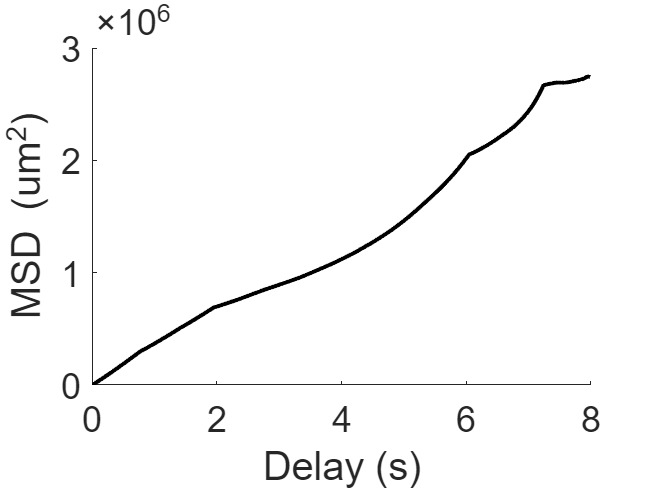

% The grayed area represents the weighted standard deviation over all separate MSD tracks
set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])


% %with error bars
% mmsd = ma.getMeanMSD(1:numel(ma.msd)); %was getting indices error with empty input so I changed it to 1:numel(ma.msd)
% t = mmsd(:,1);
% x = mmsd(:,2);
% dx = mmsd(:,3) ./ sqrt(mmsd(:,4));
% errorbar(t, x, dx, 'k')


clf;
ma = ma.computeDrift('velocity');
figure
ma.plotMeanMSD(gca,false)

Computing MSD of 100 tracks...   Done.


set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])


xma = xma.computeDrift('velocity');
figure 
xma.plotMeanMSD(gca,false)

Computing MSD of 100 tracks...   Done.


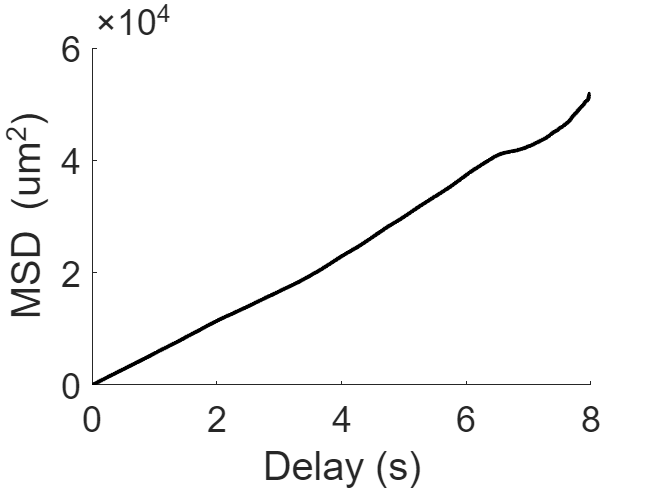

set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])


yma = yma.computeDrift('velocity');
figure
yma.plotMeanMSD(gca,false)

Computing MSD of 100 tracks...   Done.


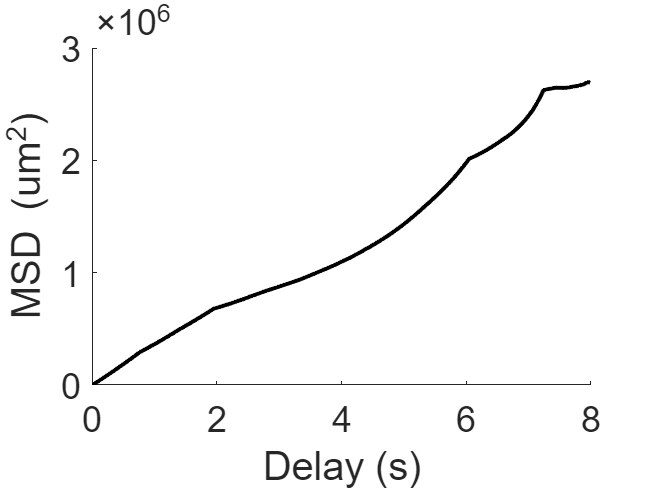

set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])

%%%This is to combine multiple already created and saved MSD figures
% List of full path names for the figure files to be combined
filePaths = {
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa1mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa035mA NHDS MSD.fig', ... % Blue shades
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa1mA NHDS MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa035mA MSD.fig', ... % Red shades
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa1mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa035mA MSD.fig'      % Green shades
};


% Create a new figure
combinedFigure = figure;

% Define color sets
blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7]; % Shades of green

% Loop through each file
for i = 1:numel(filePaths)
    % Load the figure file
    loadedFig = openfig(filePaths{i}, 'invisible');
    
    % Get the handle of the axes in the loaded figure
    axesHandle = gca(loadedFig);
    
    % Determine the color set based on the index
    if i <= 3
        colorSet = blueShades(i,:);
    elseif i <= 6
        colorSet = redShades(i-3,:);
    else
        colorSet = greenShades(i-6,:);
    end
    
    % Get the number of lines in the axes
    numLines = numel(axesHandle.Children);
    
    % Copy the line data onto the combined figure with different colors
    for j = 1:numLines
        lineData = axesHandle.Children(j).YData;
        lineColor = colorSet(rem(j-1, size(colorSet, 1)) + 1, :);
        normalizedData = lineData / max(lineData);  % Normalize YData
        
        figure(combinedFigure);  % Switch focus to the combined figure
        hold on;
        plot(lineData, 'Color', lineColor,'LineWidth',1.5); %choose lineData or normalizedData
      
    end
    
    % Close the loaded figure
    close(loadedFig);
end

% Adjust the layout if needed
% For example, you can use the 'subplot' function to arrange the subplots


% Set legend labels for each set of three figures
legendLabels = {
    '70Pa 1mA', '70Pa 0.7mA', '70Pa 0.35mA NHDS', ...
    '46Pa 1mA NHDS', '46Pa 0.7mA', '46Pa 0.35mA', ...
    '30Pa 1mA', '30Pa 0.7mA', '30Pa 0.35mA'
};

% Add a legend
legend(legendLabels);

% Add title and axis labels
title('Combined MSD');
xlabel('Delay (\tau)');
ylabel('MSD(\tau)');
axis([0 1000 0 1000000])

ax = gca;
ax.XTickLabel = {'0','2','4','6','8','10'};


## Polynomial Fitting for MSD

%after calculating A you can comment it on so as to not repeat MeanMSD
%calculation but check fitting
A = ma.getMeanMSD(1:numel(ma.msd));

Computing MSD of 100 tracks...   Done.


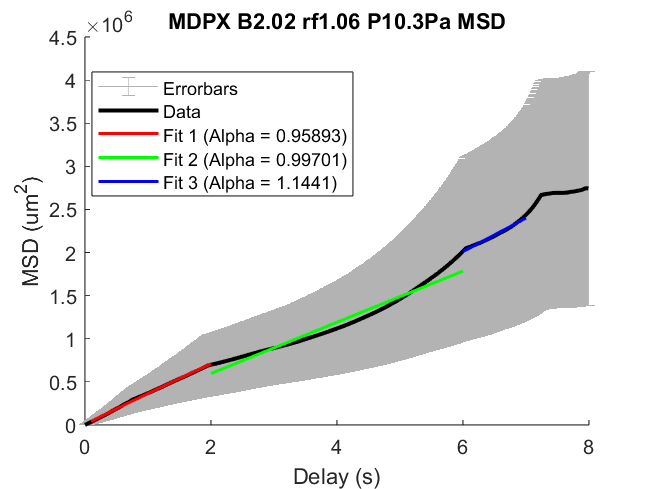

t = A(:, 1); % delay vector
msd = A(:, 2); % msd
std_msd = A(:, 3); % we will use inverse of the std as weights for the fit
std_msd(1) = std_msd(2); % avoid infinity weight
line_fit_limit = 0.9; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(t); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 0.1; % Start of the first polynomial fit
polyFits(1).finish = 2; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

polyFits(2).start = 2; % Start of the second polynomial fit
polyFits(2).finish = 6; % End of the second polynomial fit
polyFits(2).coefficients = [0, 1.5]; 

polyFits(3).start = 6; % Start of the third polynomial fit
polyFits(3).finish = 7; % End of the third polynomial fit
polyFits(3).coefficients = [0, 1.5]; 
% 
% polyFits(4).start = 4; % Start of the fourth polynomial fit
% polyFits(4).finish = 11; % End of he fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 

% polyFits(5).start = 11; % Start of the fith polynomial fit
% polyFits(5).finish =16; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% 
% polyFits(6).start = 16.5; % Start of the fith polynomial fit
% polyFits(6).finish = 18; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1]; 

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

bars = A(:,3) ./ sqrt(A(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(t, msd, bars, 'Color', [0.7 0.7 0.7 0.5]);
plot(t, msd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(t >= polyFits(i).start, 1);
    finishIdx = find(t <= polyFits(i).finish, 1, 'last');
    weights = 1./std_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(t(startIdx:finishIdx), msd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa MSD');
ma.labelPlotMSD;

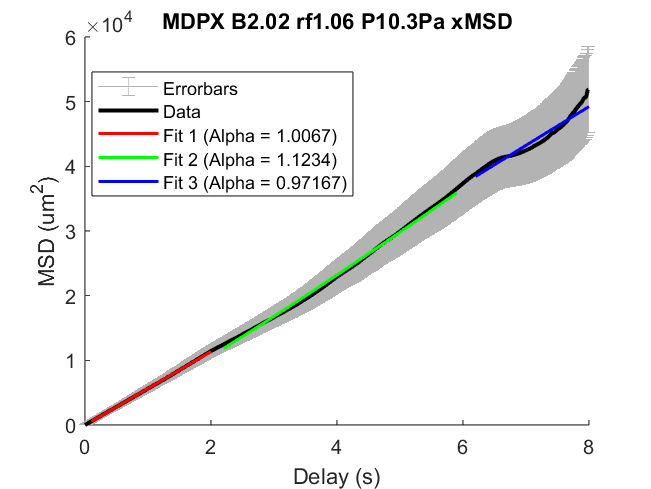

%same thing for x direction MSD
%Ax = xma.getMeanMSD(1:numel(xma.msd));
tx = Ax(:, 1); % delay vector
xmsd = Ax(:, 2); % msd
xstd_msd = Ax(:, 3); % we will use inverse of the std as weights for the fit
xstd_msd(1) = xstd_msd(2); % avoid infinity weight
line_fit_limit = 1; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(tx); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 0.1; % Start of the first polynomial fit
polyFits(1).finish = 2; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

polyFits(2).start = 2.2; % Start of the second polynomial fit
polyFits(2).finish = 5.9; % End of the second polynomial fit
polyFits(2).coefficients = [0, 1.5]; 

polyFits(3).start = 6.2; % Start of the third polynomial fit
polyFits(3).finish = 8; % End of the third polynomial fit
polyFits(3).coefficients = [0, 1.5]; 
% 
% polyFits(4).start = 6.3; % Start of the fourth polynomial fit
% polyFits(4).finish = 8; % End of the fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 
% % 
% polyFits(5).start = 8; % Start of the fith polynomial fit
% polyFits(5).finish = 9; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% % 
% polyFits(6).start = 9; % Start of the fith polynomial fit
% polyFits(6).finish = 9.8; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1.5]; 
% %  

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

xbars = Ax(:,3) ./ sqrt(Ax(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(tx, xmsd, xbars, 'Color', [0.7 0.7 0.7 0.5]);
plot(tx, xmsd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(tx >= polyFits(i).start, 1);
    finishIdx = find(tx <= polyFits(i).finish, 1, 'last');
    weights = 1./xstd_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(tx(startIdx:finishIdx), xmsd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa xMSD'); %Manually adjust title each time
xma.labelPlotMSD;

%same thing for x direction MSD
Ay = yma.getMeanMSD(1:numel(yma.msd));
ty = Ay(:, 1); % delay vector
ymsd = Ay(:, 2); % msd
ystd_msd = Ay(:, 3); % we will use inverse of the std as weights for the fit
ystd_msd(1) = ystd_msd(2); % avoid infinity weight
line_fit_limit = 1; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(ty); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 0.1; % Start of the first polynomial fit
polyFits(1).finish = 2; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

polyFits(2).start = 2; % Start of the second polynomial fit
polyFits(2).finish = 6; % End of the second polynomial fit
polyFits(2).coefficients = [0, 1.5]; 

polyFits(3).start = 6; % Start of the third polynomial fit
polyFits(3).finish = 7; % End of the third polynomial fit
polyFits(3).coefficients = [0, 1.5]; 

% polyFits(4).start = 0.014; % Start of the fourth polynomial fit
% polyFits(4).finish = 0.028; % End of he fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 
% 
% polyFits(5).start = 0.1; % Start of the fith polynomial fit
% polyFits(5).finish =0.4; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% 
% polyFits(6).start = 0.028; % Start of the fith polynomial fit
% polyFits(6).finish = 0.1; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1]; 

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

ybars = Ay(:,3) ./ sqrt(Ay(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(ty, ymsd, ybars, 'Color', [0.7 0.7 0.7 0.5]);
plot(ty, ymsd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(ty >= polyFits(i).start, 1);
    finishIdx = find(ty <= polyFits(i).finish, 1, 'last');
    weights = 1./ystd_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(ty(startIdx:finishIdx), ymsd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa yMSD'); %Manually adjust title each time
yma.labelPlotMSD;

## Creating Position Distributions

%%%%%%%%%% Find histogram of spacial dimension 
tracks=ma.tracks
Nparticle = numel(tracks); %find the size of tracks where each track is a separate particle. 
dx = []; %creating empty arrays which will be used to store the displacements for each particle
dy = []; %in the x and y direction respectively
Tdx = []; %this will be the array for displacements of every particle
Tdy = []; %x and y respectively 

%go through each particle from 1 to Nparticles
for i=1:Nparticle(1);
    particle = tracks{i,1}; %this pulls the i'th particle out of the cell tracks
    xdrift = particle(:,2); %this is all x positions 
    x = xdrift - mean(xdrift); %subtract mean of all positions to account for drift
    ydrift = particle(:,3); %this is all y positions
    y = ydrift - mean(ydrift); %subtract mean of all positions to account for drift
    xsteps = numel(x); %this is how many total x or y positions there are
    ysteps = numel(y);
    dx = []; %resets the array dx and dy for each particle new
    dy = []; 

    %Now that we have our particle and the number of displacements in x and
    %y we are going to find the difference in those displacements
    %respectively 

    %each for loop goes through and takes the difference between x(j) and
    %x(j+1) then appends it to the array dx
    for j = 1:xsteps(1)-1;
        dx(end+1) = diff(x(j:j+1));
    end
    
    %similarly 
    for k = 1:ysteps(1)-1;
        dy(end+1) = diff(y(k:k+1));
    end
   

    lx = numel(dx); %how many difference appended to array dx
    ly = numel(dy);
    counts = 500; %an arbitrary number picked as a cut off for whether or not dx (dy)
    %should be added to Tdx (Tdy) 
    %this is because possible the particle was not tracked over very many
    %displacements and so might not be as accurate thus this is to control
    %the accuracy or error of the data

    if lx > counts
        Tdx = [Tdx, dx];
    end 

    if ly > counts
        Tdy = [Tdy,dy];
    end 

end

%Plot position histograms
%histogram(Tdx)
clf;
Tx = transpose(Tdx);
histfit(Tx,3000)
xlim([-40 40])
pdx = fitdist(Tx,'Normal')

%histogram(Tdy)
clf;
Ty = transpose(Tdy);
histfit(Ty,3000)
xlim([-40 40])
pdy = fitdist(Ty,'Normal')

[Nxx,edges_x,bins_x]=histcounts(Tx);
domx = size(Nxx);
domainx = domx(2);
X = 1:1:domainx;
bar(X,Nxx)

[Nyy,edges_y,bins_y]=histcounts(Ty);
domy = size(Nyy);
domainy = domy(2);
Y = 1:1:domainy;
bar(Y,Nyy)

% Maxwellian distribution for positions
%modelFun = @(p,x) p(1).*exp(-(x.^2)./(v_d.^2)); % Equation used for the fit
modelFun = @(p,x) p(1).*exp(-(((x-p(3)))./p(2)).^2); % Gaussian

% Fit for X

M_xstart = [7000,20,400]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
M_x = nlinfit(X,Nxx,modelFun,M_xstart);
M_x_eval = modelFun(real(M_x),X);


% Fit for Y

M_ystart = [10000,20,380]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
M_y = nlinfit(Y,Nyy,modelFun,M_ystart);
M_y_eval = modelFun(real(M_y),Y);


% Q-Gaussian distribution for positions
% This distribution was suggested in (Liu, et al., AIP Conference Proceedings. Vol. 1925. No. 1. AIP Publishing LLC, 2018).
 modelFun = @(p,x)  real(abs(p(1))./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1)))); % Equation used for the fit

% Fit for x

Q_xstart = [8000,380,8,1.1];
Q_x = nlinfit(X,Nxx,modelFun,Q_xstart);
Q_x_eval = modelFun(real(Q_x),X);

% Fit for y

Q_ystart = [10000,380,12,1];
Q_y = nlinfit(Y,Nyy,modelFun,Q_ystart);
Q_y_eval = modelFun(real(Q_y),Y);

%super and super without normalization 
modelFun = @(p,x) (abs(p(1))./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1)))) + (abs(p(1))./((1+((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^2)))).^(1/(p(7)-1))));  
%qsup normalization sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi.*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*
%qsub normalization sqrt((gamma((2-abs(p(4)))./(1-abs(p(4)))))./(pi.*sqrt(1-abs(p(4))).*gamma((5-3*abs(p(4)))./(2-2*abs(p(4))))))

% Fit for Vy
Qsb_ystart = [5000,380,10,1.5,380,10,1.01];
Qsb_y = nlinfit(Y,Nyy,modelFun,Qsb_ystart);
Qsb_y_eval = modelFun(real(Qsb_y),Y);

% Plot the histograms of x_differences and fit different distributions
figure
bar(X,Nxx)
box off
hold on
plot(X,M_x_eval,'k','LineWidth',2); % Fit Gaussian distribution to the histogram
plot(X,Q_x_eval,'m','LineWidth',2); % Fit Q-Gaussian distribution to the histogram
plot(0,0,'w'); %this is to create extra legend space
title('Field-aligned Position difference PDF 70Pa 0.35mA') % Change the title to reflect the parameters of the dataset used
xlabel([ 'x(t)-<x(t)>' ])
ylabel('Counts')
xlim([300 460])
set(gca,'FontSize',18); % Set axis fornsize to 18
plot(0,0,'w'); %this is to create extra legend space
legend({['{x} x_0=' num2str(M_x(3),'%.3f')], ['Msigma=' num2str(M_x(2))], ['q=' num2str(Q_x(4)) ' qsigma=' num2str(abs(Q_x(3)), '%.3f')],['Counts ' num2str(abs(Q_x(1)),'%.2f')]}, 'Location', 'northeast');

% Plot the histograms of y_differences and fit different distributions
figure
bar(Y,Nyy)
box off
hold on
plot(Y,M_y_eval,'k','LineWidth',2); % Fit Gaussian distribution to the histogram
plot(Y,Q_y_eval,'m','LineWidth',2); % Fit Q-Gaussian distribution to the histogram
plot(Y,Qsb_y_eval,'g','LineWidth',2); % Fit Bi-Q-Gaussian distribution to the histogram
plot(0,1,'w'); %for extra legend entries
plot(0,1,'w'); 
xlabel(['y(t)-<y(t)>'])
ylabel('Counts')
xlim([300 430])
set(gca,'FontSize',18); % Set axis fornsize to 18
title('Crossfield Position difference PDF 70Pa 0.35mA') % Change the title to reflect the parameters of the dataset used
%legend({['v_{x} v_x_0=' num2str(M_y(3))], ['Mvth=' num2str(M_y(2))], ['q=' num2str(Q_y(4)) ' qvth=' num2str(Q_y(3))],['Counts ' num2str(Q_x(1),'%.2f')]}, 'Location', 'northeast');
legend({['{y} y_0=' num2str(Q_y(2),'%.3f')], ['Msigma=' num2str(M_y(2),'%.3f')], ['q=' num2str(Q_y(4),'%.3f') ' qsigma=' num2str(Q_y(3),'%.3f')],['qsp1=' num2str(real(Qsb_y(4)),'%.3f') ' qsp2=' num2str(real(Qsb_y(7)),'%.3f')],['qsigma1=' num2str(real(Qsb_y(3)),'%.3f') ' qsigma2=' num2str(real(Qsb_y(6)),'%.3f')],['qsp Counts ' num2str(real(Qsb_y(1)),'%.2f')]}, 'Location', 'northeast','AutoUpdate','on');

## Extract velocities and piecewise function from velocity histograms

%%%%%%%%%%%%%% must run this
N_TIME_STEPS = 800;

trackV = ma.getVelocities; % Retrieve instantaneous velocities, per track
TV = vertcat( trackV{:} ); % Pool track data together
% Velocities are returned in a N x (nDim+1) array: [ T Vx Vy ...]. So the
% velocity vector in 2D is:
V = TV(:, 2:3);


[Nx,Xx] = hist(V(:,1),(N_TIME_STEPS/2)); % Extract the piecewise function data from the Vx histogram,
% i.e., the function obtained by connecting the heights of the bars.

[Ny,Xy] = hist(V(:,2),(N_TIME_STEPS/2)); % Extract the piecewise function data from the Vy histogram,
% i.e., the function obtained by connecting the heights of the bars.

%[Nr,Xr] = hist(V(:,3),(N_TIME_STEPS/2)); % Extract the piecewise function data from the Vy histogram,
% i.e., the function obtained by connecting the heights of the bars.

%Y_Vx = Nx/(sum(Nx))/diff(Xx(389:390)); % Number of counts normalized by the total area of the distribution
%Y_Vy = Ny/(sum(Ny))/diff(Xy(389:390));
%Y_Vr = Nr/(sum(Nr))/diff(Xr(389:390));

## Extract Velocities for single direction MSD

N_TIME_STEPS = 800;
%these should make the same histograms as above

trackVx=xma.getVelocities;
TVx = vertcat( trackVx{:} );
Vx = TVx(:,2);
[Nx,Xx] = hist(Vx(:,1),(N_TIME_STEPS));

trackVy=yma.getVelocities;
TVy = vertcat( trackVy{:} );
Vy = TVy(:,2);
[Ny,Xy] = hist(Vy(:,1),(N_TIME_STEPS));

%Creating a Vr histogram
% Square all values in Vx and Vy
Vx_squared = Vx.^2;
Vy_squared = Vy.^2;

% Add the squared doubles together
Vrsquare = Vx_squared + Vy_squared;

% Take the square root of the result
Vr = sqrt(Vrsquare);
[Nr,Xr] = hist(Vr(:,1),(N_TIME_STEPS/2));

## Extract Velocities between a certain time delay thresholds 

N_TIME_STEPS = 1428;

trackV = ma.getVelocities; % Retrieve instantaneous velocities, per track

t_min = 8.00;
t_max = 11.00;
Total_particles =  numel(trackV);
lim_trackV=[];

for i=1:Total_particles
    particle = trackV{i,1};
    if particle(1,1) < t_max && particle(1,1) >= t_min
        lim_trackV{i,1} = trackV{i,1};
    end
end


TV = vertcat( lim_trackV{:} ); % Pool track data together
% Velocities are returned in a N x (nDim+1) array: [ T Vx Vy ...]. So the
% velocity vector in 2D is:
V = TV(:, 2:3);

[Nx,Xx] = hist(V(:,1),(N_TIME_STEPS/2)); % Extract the piecewise function data from the Vx histogram,
% i.e., the function obtained by connecting the heights of the bars.

[Ny,Xy] = hist(V(:,2),(N_TIME_STEPS/2)); % Extract the piecewise function data from the Vy histogram,
% i.e., the function obtained by connecting the heights of the bars.


## Extract velocities for certain domains

DomVel=[];
N_TIME_STEPS = 1428;

for i=1:numel(Allma)
    currentma=Allma{i};
    currentv=currentma.getVelocities;
    TV = vertcat( currentv{:} ); 
    V = TV(:, 2:3);
    DomVel{i}=V;
end

DV=DomVel{1}; %select domain ex: DomVel{5}=velocities for domain 21

[Nx,Xx] = hist(DV(:,1),(N_TIME_STEPS/2)); 
[Ny,Xy] = hist(DV(:,2),(N_TIME_STEPS/2)); 


## Fit various distribution functions to velocity histograms

The # of bins for all histograms is estimated to be 1000, wich is about the ratio between the larges and the smallest velocity, as expected from experiment and particle tracking.

% Maxwellian distribution
%modelFun = @(p,x) p(1).*exp(-(x.^2)./(v_d.^2)); % Equation used for the fit
modelFun = @(p,x) (1./(sqrt(2*pi)*p(2))).*p(1).*exp(-0.5*(((x-p(3)))./p(2)).^2); % Gaussian

% Fit for Vx
M_Vxstart = [800,10,0]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
%M_Vx = nlinfit(Xx,Y_Vx,modelFun,M_Vxstart); % Extract the values of the free parameters as calculated from the fit.
M_Vx = nlinfit(Xx,Nx,modelFun,M_Vxstart);
M_Vx_eval = modelFun(real(M_Vx),Xx);

% Fit for Vy
M_Vystart = [800,1,0]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
%M_Vy = nlinfit(Xy,Y_Vy,modelFun,M_Vystart); % Extract the values of the free parameters as calculated from the fit.
M_Vy = nlinfit(Xy,Ny,modelFun,M_Vystart);

M_Vy_eval = modelFun(real(M_Vy),Xy);

%Rayleigh Distribution A Rayleigh distribution is often observed when the overall magnitude of a vector is related to its directional components.
%One example where the Rayleigh distribution naturally arises is when wind velocity is analyzed in two dimensions.
% Assuming that each component is uncorrelated, normally distributed with equal variance, and zero mean, then the overall wind speed (vector magnitude) will be characterized by a Rayleigh distribution.
modelFun = @(p,x) ((x-p(3))./(sqrt(0.5*pi*p(2).^2))).*p(1).*exp(-0.5*(((x-p(3)))./p(2)).^2); % Rayleigh
%fit for Vx
R_Vxstart = [7000,30,-80]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
R_Vx = nlinfit(Xx,Nx,modelFun,R_Vxstart);
R_Vx_eval = modelFun(real(R_Vx),Xx);
%fit for Vy
R_Vystart = [7000,30,-80]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
R_Vy = nlinfit(Xy,Ny,modelFun,R_Vystart);
R_Vy_eval = modelFun(real(R_Vy),Xy);

%Inverse Gaussian distribution or Wald Distribution
%the inverse Gaussian describes the distribution of the time a Brownian motion with positive drift takes to reach a fixed positive level
modelFun = @(p,x) sqrt((real(p(2))./((2*pi).*(x.^3)))).*real(p(1)).*exp(-0.5*(real(p(2))./(x)).*(((x-real(p(3))))./real(p(3))).^2); 

% Fit for Vx
W_Vxstart = [6000,50,50]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
%M_Vx = nlinfit(Xx,Y_Vx,modelFun,M_Vxstart); % Extract the values of the free parameters as calculated from the fit.
W_Vx = nlinfit(Xx,Nx,modelFun,W_Vxstart);
W_Vx_eval = modelFun(real(W_Vx),Xx);

% Fit for Vy
W_Vystart = [6000,100,-100]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
%M_Vy = nlinfit(Xy,Y_Vy,modelFun,M_Vystart); % Extract the values of the free parameters as calculated from the fit.
W_Vy = nlinfit(Xy,Ny,modelFun,W_Vystart);
W_Vy_eval = modelFun(real(W_Vy),Xy);

%Levy Distribution
modelFun = @(p,x) (sqrt(p(2)./(2*pi*((x-p(3)).^3)))).*p(1).*exp(-0.5*(p(2)./(x-p(3)))); 
%fit for Vx
L_Vxstart = [7000,25,-80]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
L_Vx = nlinfit(Xx,Nx,modelFun,L_Vxstart);
L_Vx_eval = modelFun(real(L_Vx),Xx);
%fit for Vy
L_Vystart = [7000,25,-80]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
L_Vy = nlinfit(Xy,Ny,modelFun,L_Vystart);
L_Vy_eval = modelFun(real(L_Vy),Xy);

%Gamma Distribution
modelFun = @(p,x) p(1).*exp(-(x-p(2))./p(3)).*((x-p(2)).^(p(4))).*(p(3).^(-p(4)+1))./gamma(real(p(4)+1));
%fit for Vx
G_Vxstart = [70000,-200,57.2,1.58]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
G_Vx = nlinfit(Xx,Nx,modelFun,G_Vxstart);
G_Vx_eval = modelFun(real(G_Vx),Xx);
%fit for Vy
G_Vystart = [70000,-200,57,1.6]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
G_Vy = nlinfit(Xy,Ny,modelFun,L_Vystart);
G_Vy_eval = modelFun(real(G_Vy),Xy);

clf;
p=[350,-200,50,2];
x = [-500:1:500]
f = p(1).*(exp(-(x-p(2))./p(3)).*((x-p(2)).^(p(4))).*(p(3).^(1-p(4))))./gamma(real(p(4)+1));
plot(x,f)
xlim([-200 500])

% Maxwellian + Kappa(**n) distribution (old fit)
% This distribution was suggested in (Liu, et al., AIP Conference Proceedings. Vol. 1925. No. 1. AIP Publishing LLC, 2018).
 %modelFun = @(p,x) p(1).*exp(-(x.^2)./(v_d).^2)+p(1)./((1+((x.^2)./((p(2).^(p(3))).*(v_d).^2)))).^p(2); % Equation used for the fit
 modelFun = @(p,x) p(1).*exp(-((x-p(6)).^2)./p(2).^2)+p(5)./((1+(((x-p(6)).^2)./((p(3).^(p(4)).*p(2).^2)))).^p(3));

% Fit for Vx
MKn_Vxstart = [6000,300,3,2,10000,11];
%MKn_Vx = nlinfit(Xx,Y_Vx,modelFun,MKn_Vxstart);
MKn_Vx = nlinfit(Xx,Nx,modelFun,MKn_Vxstart);
MKn_Vx_eval = modelFun(real(MKn_Vx),Xx);

% Fit for Vy
MKn_Vystart = [2000,200,2,4,5000,0];
%MKn_Vy = nlinfit(Xy,Y_Vy,modelFun,MKn_Vystart);
MKn_Vy = nlinfit(Xy,Ny,modelFun,MKn_Vystart);
MKn_Vy_eval = modelFun(real(MKn_Vy),Xy);

% Kappa distribution 
% This distribution was suggested in (Liu, et al., AIP Conference Proceedings. Vol. 1925. No. 1. AIP Publishing LLC, 2018).
 modelFun = @(p,x) abs(p(1))./((1+((((x-p(4))).^2)./(((p(3).^2).^(1/2)).*(abs(p(2)).^2)))).^p(3)); % Equation used for the fit

% Fit for Vx
K_Vxstart = [8000,500,10,0];
%MK_Vx = nlinfit(Xx,Y_Vx,modelFun,MK_Vxstart);
K_Vx = nlinfit(Xx,Nx,modelFun,K_Vxstart);
K_Vx_eval = modelFun(real(K_Vx),Xx);


% Fit for Vy
K_Vystart = [8000,500,2,0];
%MK_Vy = nlinfit(Xy,Y_Vy,modelFun,MK_Vystart);
K_Vy = nlinfit(Xy,Ny,modelFun,K_Vystart);
K_Vy_eval = modelFun(real(K_Vy),Xy);

%Barenblat-Pattle Solution (a type of q-gaussian) plus Maxwellian (old fit)
%((p(3)+p(3).^2).*(sqrt(pi./(1-p(3))).*(gamma(p(3)./(1-p(3)))./gamma((3.*p(3)-1)./(2.*p(3)-2))).^(1-p(3)))).^(-2./(1+p(3)))
 modelFun = @(p,x) real(p(1).*exp(-(((x-p(5))).^2)./(abs(p(2)).^2)) + (sqrt(1/(p(2).^(1/(1+p(3)))))).*p(4)./((1-((((p(3)+p(3).^2).*(sqrt(pi./(1-p(3))).*(gamma(p(3)./(1-p(3)))./gamma((3.*p(3)-1)./(2.*p(3)-2))).^(1-p(3)))).^(-2./(1+p(3))).*((x-p(5))).^2)./(((1-abs(p(3)))^(-1)).*(abs(p(2)).^(2/(1+abs(p(3)))))))).^(1/(1-abs(p(3)))))); % Equation used for the fit

% Fit for Vx
BB_Vxstart = [100,500,1.2,1000,0];
BB_Vx = nlinfit(Xx,Nx,modelFun,BB_Vxstart);
BB_Vx_eval = modelFun(real(BB_Vx),Xx);

%Barenblat-Pattle Solutions (porous medium) for vy needs gaussian 

% Fit for Vy
BB_Vystart = [10000,500,0.3,1000,0];
BB_Vy = nlinfit(Xy,Ny,modelFun,BB_Vystart);
BB_Vy_eval = modelFun(real(BB_Vy),Xy);

% single superdiff Q-Gaussian distribution with proper normalizations
% This distribution was suggested in (Liu, et al., AIP Conference Proceedings. Vol. 1925. No. 1. AIP Publishing LLC, 2018).
%modelFun = @(p,x)  sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*real(abs(p(1))./((1+((gamma((3-p(4))./(2.*p(4)-2)))./(sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1)))).*(1/abs(p(3))); % Equation used for the fit

%%below without normalization (with or without norm does not change fitted
%%parameters except for p(1)
modelFun = @(p,x)  abs(p(1)).*(1./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2))))).^(1/(p(4)-1))));

%with q (p(4)) on variance/themal velocity (p(3))
%%below with normalization
%modelFun = @(p,x)  abs(p(1))*sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi.*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*(1./((1+((gamma((3-p(4))./(2.*p(4)-2)))./(sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2/(3-p(4))))))).^(1/(p(4)-1))))*(1/(p(3).^(1/(3-p(4))))); 

% Fit for Vx
Q_Vxstart = [800,0,10,1.9];
Q_Vx = nlinfit(Xx,Nx,modelFun,Q_Vxstart);
Q_Vx_eval = modelFun(real(Q_Vx),Xx);

% Fit for Vy
Q_Vystart = [800,0,10,1.01];
Q_Vy = nlinfit(Xy,Ny,modelFun,Q_Vystart);

Q_Vy_eval = modelFun(real(Q_Vy),Xy);

% Q-Gaussian fits // distribution is superdiffusion p(4) then plus another superdiffusion or sub p(7)

%super and super with normalizations
%modelFun = @(p,x) sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi.*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*real(abs(p(1))./((1+((gamma((3-p(4))./(2.*p(4)-2)))./(sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2/(3-p(4))))))).^(1/(p(4)-1))))*(1/(abs(p(3)).^(1/(3-p(4))))) + sqrt((gamma((3-p(7))./(2.*p(7)-2)))./(pi.*sqrt(p(7)-1).*gamma(1./(p(7)-1)))).*real(abs(p(1))./((1+((gamma((3-p(7))./(2.*p(7)-2)))./(sqrt(p(7)-1).*gamma(1./(p(7)-1)))).*((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^(2/(3-p(7))))))).^(1/(p(7)-1))))*(1/(abs(p(6)).^(1/(3-p(7))))); %includes normalizations
 
%subdiff and super which has issue with complex numbers somehow
%modelFun = @(p,x) abs((p(1))./((1+(1./(pi.*sqrt(1-abs(p(4))))).*((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2))))).^(1/(p(4)-1)))).*(abs(p(3)).^(-1)) + abs(p(1))./((1+((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^2)))).^(1/(p(7)-1))).*(1./abs(p(6))); 

%super and super without normalization 
modelFun = @(p,x) (abs(p(1))./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1)))) + (abs(p(1))./((1+((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^2)))).^(1/(p(7)-1))));  
%qsup normalization sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi.*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*
%qsub normalization sqrt((gamma((2-abs(p(4)))./(1-abs(p(4)))))./(pi.*sqrt(1-abs(p(4))).*gamma((5-3*abs(p(4)))./(2-2*abs(p(4))))))

% Fit for Vy
Qsb_Vystart = [400,0,10,1.4,0,10,1.4];
Qsb_Vy = nlinfit(Xy,Ny,modelFun,Qsb_Vystart);

Qsb_Vy_eval = modelFun(real(Qsb_Vy),Xy);

%all different fits for Vr
MmodelFun = @(p,x) ((x.^1)./(sqrt(0.5*pi)*p(2))).*p(1).*exp(-0.5*(((x-p(3)))./p(2)).^2); % Gaussian

M_Vrstart = [7000,500,-1000]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
%M_Vx = nlinfit(Xx,Y_Vx,modelFun,M_Vxstart); % Extract the values of the free parameters as calculated from the fit.
M_Vr = nlinfit(Xr,Nr,MmodelFun,M_Vrstart);
M_Vr_eval = MmodelFun(real(M_Vr),Xr);

%Q fit for Vr
QmodelFun = @(p,x)  (x.^1).*abs(p(1))*sqrt((gamma((3-p(4))./(2.*p(4)-2)))./(pi.*sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*(1./((1+((gamma((3-p(4))./(2.*p(4)-2)))./(sqrt(p(4)-1).*gamma(1./(p(4)-1)))).*((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^(2/(3-p(4))))))).^(1/(p(4)-1))))*(1/(p(3).^(1/(3-p(4)))));

Q_Vrstart = [70000,400,3000,1.5]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
Q_Vr = nlinfit(Xr,Nr,QmodelFun,Q_Vrstart);
Q_Vr_eval = QmodelFun(real(Q_Vr),Xr);

% % Qsb Fit for Vr
% sbmodelFun = @(p,x) (x.^(2)).*abs(p(1))./((1+((((x-p(2))).^2)./(((p(4)-1)^(-1)).*(abs(p(3)).^2)))).^(1/(p(4)-1))) + abs(p(1))./((1+((((x-p(5))).^2)./(((p(7)-1)^(-1)).*(abs(p(6)).^2)))).^(1/(p(7)-1))); % does not include normalizations 
% 
% Qsb_Vrstart = [6000,700,700,1.1,700,90,2]; % Starting values are our best initial guess for the free parametrrs p(1), p(2), etc.
% %M_Vx = nlinfit(Xx,Y_Vx,modelFun,M_Vxstart); % Extract the values of the free parameters as calculated from the fit.
% Qsb_Vr = nlinfit(Xr,Nr,sbmodelFun,Qsb_Vrstart);
% Qsb_Vr_eval = sbmodelFun(real(Qsb_Vr),Xr);

clf;
p=[230,-200,50,2];
x = [-500:1:500]
f = p(1).*(exp(-(x-p(2))./p(3)).*((x-p(2)).^(p(4))).*(p(3).^(1-p(4))))./gamma(real(p(4)+1));
plot(x,f,'g','Linewidth',2)
xlim([-200 500])

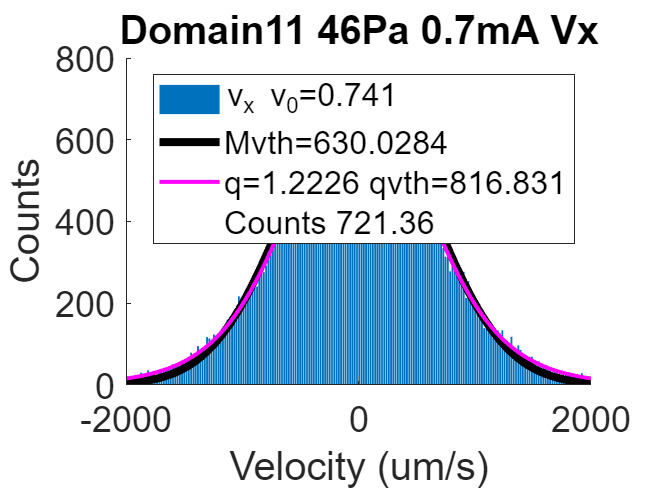

SPACE_UNITS = 'um';
TIME_UNITS = 's';
% Plot the histograms of x_velocities and fit different distributions
figure
bar(Xx,Nx)
box off
hold on
plot(Xx,M_Vx_eval,'k','LineWidth',4); % Fit Gaussian distribution to the histogram
%plot(Xx,R_Vx_eval,'g','Linewidth',2); %Fit Rayleigh Distribution
%plot(Xx,W_Vx_eval,'g','Linewidth',2); %Fit Wald Distribution
%plot(Xx,L_Vx_eval,'g','Linewidth',2); %Fit Levy Distribution
%plot(Xx,G_Vx_eval,'g','Linewidth',2); %Fit Gamma Distribution
%plot(Xx,MKn_Vx_eval,'r','LineWidth',2); % Fit Maxwellian + Kappa distribution to the histogram
%plot(Xx,MK_Vx_eval,'g','LineWidth',2); % Fit Kappa distribution to the histogram
plot(Xx,Q_Vx_eval,'m','Linewidth',2); %Fit Q Gaussian (Best fit)
%plot(Xx,Qv_Vx_eval,'g','Linewidth',2); %
plot(0,0,'w'); %this is to create extra legend space
title('Domain11 46Pa 0.7mA Vx') % Change the title to reflect the parameters of the dataset used
xlabel([ 'Velocity (' SPACE_UNITS '/' TIME_UNITS ')' ])
ylabel('Counts')
xlim([-2000 2000])
set(gca,'FontSize',18); % Set axis fornsize to 18
plot(0,0,'w'); %this is to create extra legend space
legend({['v_{x} v_x_0=' num2str(M_Vx(3),'%.3f')], ['Mvth=' num2str(M_Vx(2))], ['q=' num2str(Q_Vx(4)) ' qvth=' num2str(abs(Q_Vx(3)), '%.3f')],['Counts ' num2str(abs(Q_Vx(1)),'%.2f')]}, 'Location', 'northeast');

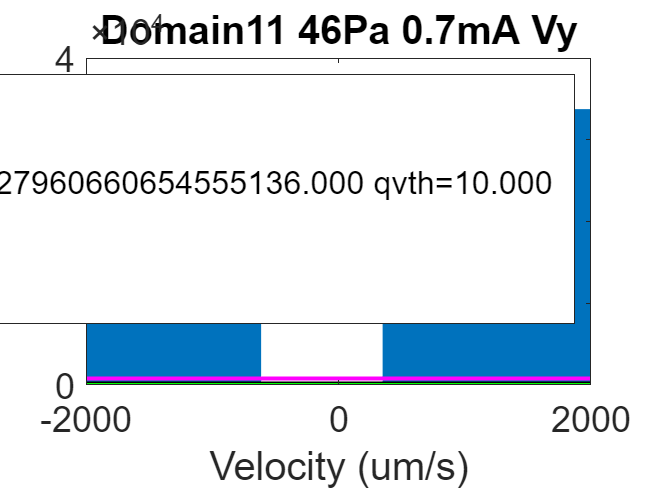

SPACE_UNITS = 'um';
TIME_UNITS = 's';
%y-componenet velocities
figure
bar(Xy,Ny)
box on
hold on
plot(Xy,M_Vy_eval,'k','LineWidth',3.5); % 
%plot(Xx,R_Vy_eval,'g','Linewidth',2); %Fit Rayleigh Distribution
%plot(Xx,L_Vx_eval,'g','Linewidth',2); %Fit Levy Distribution
%plot(Xy,MK_Vy_eval,'g','LineWidth',2); % 
%plot(Xy,MKn_Vy_eval,'g','LineWidth',2); % 
%plot(Xy,K_Vy_eval,'m','LineWidth',2); % 
plot(Xy,Q_Vy_eval,'m','LineWidth',2);
%plot(Xy,MQn_Vy_eval,'g','LineWidth',2); % 
plot(Xy,Qsb_Vy_eval,'g','LineWidth',2); % 
plot(0,0,'w'); %this is to create extra legend space
plot(0,1,'w'); 
xlabel([ 'Velocity (' SPACE_UNITS '/' TIME_UNITS ')' ])
ylabel('Counts')
xlim([-2000 2000])
set(gca,'FontSize',18); % Set axis fornsize to 18
title('Domain11 46Pa 0.7mA Vy') % Change the title to reflect the parameters of the dataset used
%legend({['v_{x} v_x_0=' num2str(M_Vy(3))], ['Mvth=' num2str(M_Vy(2))], ['q=' num2str(Q_Vy(4)) ' qvth=' num2str(Q_Vy(3))],['Counts ' num2str(Q_Vx(1),'%.2f')]}, 'Location', 'northeast');
legend({['v_{y} v_y_0=' num2str(Q_Vy(2),'%.3f')], ['M vth=' num2str(M_Vy(2),'%.3f')], ['q=' num2str(Q_Vy(4),'%.3f') ' qvth=' num2str(Q_Vy(3),'%.3f')],['qsp1=' num2str(real(Qsb_Vy(4)),'%.3f') ' qsp2=' num2str(real(Qsb_Vy(7)),'%.3f')],['qvth1=' num2str(real(Qsb_Vy(3)),'%.3f') ' qvth2=' num2str(real(Qsb_Vy(6)),'%.3f')],['qsp Counts ' num2str(real(Qsb_Vy(1)),'%.2f')]}, 'Location', 'northeast','AutoUpdate','on');

## Other Side Project Sections 

%%%Example of 2D nongaussian bar plot&&&
v = -7:1:7;
mx = [1,1,2,2,3,4,8,20,8,4,3,2,2,1,1];
my = [0,0,0,1,2,3,5,6.5,5,3,2,1,0,0,0];
myt = my.';
mr = myt*mx;
xsteps=bar3(v,mr);
%%gives color to the height&&
for k = 1:length(xsteps)
    zdata = xsteps(k).ZData;
    xsteps(k).CData = zdata;
    xsteps(k).FaceColor = 'interp';
end

%% Doing the same method as the above example onto the PK4 data &&
width = 10; %% giving a smaller bar width yields more resolution and is more computational expensive &&
Xxt = Xx.';
rr = Xxt*Xy;
Nxt=Nx.';
Nr = Nxt*Ny;
srr=sqrt(rr);
Rr=rr./srr;
B = bar3(rr);
% for k = 1:length(B)
%     zdata = B(k).ZData;
%     B(k).CData = zdata;
%     B(k).FaceColor = 'interp';
% end

%%%finding acceleration distribution --- very possibly incorrect
%%%must delete old ma object after running above create velocity 
%%% section to make trackV
d11ma = msdanalyzer(2, SPACE_UNITS, TIME_UNITS);
d11ma = d11ma.addAll(trackV);
trackA = d11ma.getVelocities;
TA = vertcat( trackA{:} ); 
A = TA(:, 2:3);

[ANx,AXx] = hist(A(:,1),(N_TIME_STEPS/2)); 
[ANy,AXy] = hist(A(:,2),(N_TIME_STEPS/2));
bar(AXx,ANx)
bar(AXy,ANy)


% % Plot the histograms of r_velocities and fit different distributions
figure
title('70 Pa Vr 7mA hist')
bar(Xr,Nr)
box off
hold on
plot(Xr,M_Vr_eval,'k','LineWidth',3.5); % 
%plot(Xy,MK_Vy_eval,'g','LineWidth',2); % 
%plot(Xy,MKn_Vy_eval,'g','LineWidth',2); % 
%plot(Xy,K_Vy_eval,'m','LineWidth',2); % 
plot(Xr,Q_Vr_eval,'m','LineWidth',2);
%plot(Xy,MQ_Vy_eval,'g','LineWidth',2); % 
%plot(Xy,MQn_Vy_eval,'g','LineWidth',2); % 
%plot(Xr,Qsb_Vr_eval,'g','LineWidth',2); % 

xlabel([ 'Velocity (' SPACE_UNITS '/' TIME_UNITS ')' ])
ylabel('Counts')
xlim([0 3000])
set(gca,'FontSize',18); % Set axis fornsize to 18
title('30 Pa Vr 1mA ') % Change the title to reflect the parameters of the dataset used
legend({['v_{r} v_r_x_0=' num2str(Q_Vr(2))], ['M vth=' num2str(M_Vr(2))], ['q=' num2str(Q_Vr(4)) ' qvth=' num2str(Q_Vr(3))]}, 'Location', 'northeast');
